# FALTA LO DE LA FUNCIÓN DE TRANSFERENCIA

% --- PARTE 1: Modelo en variables de estado ---
syms k_e p V w(t)
ec1 = diff(w,t) == -p*w + k_e*V;
w_0 = w(0) == 0;
omega(t) = simplify(dsolve(ec1, w_0))

$$omega(t) = \frac{V\,k_{e}-V\,k_{e}\,{\mathrm{e}}^{-p\,t}}{p}$$


syms theta(t)
ec2 = diff(theta,t) == omega(t);
theta_0 = theta(0) == 0;
theta(t) = simplify(dsolve(ec2, theta_0))

$$theta(t) = \frac{V\,k_{e}\,\left({\mathrm{e}}^{-p\,t}+p\,t\right)}{p^{2}}-\frac{V\,k_{e}}{p^{2}}$$

Representación 

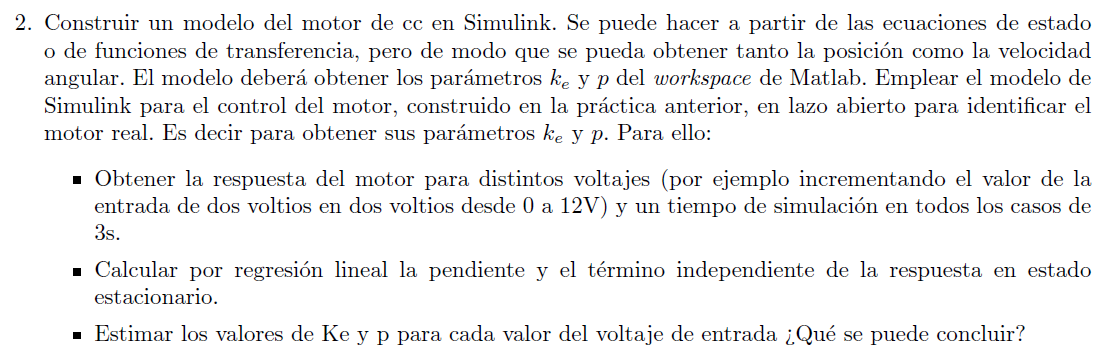

clear all, close all
% Cargar archivo:
%load('v2.mat');
d(1) = load("v2.mat");
d(2) = load("v4.mat");
d(3) = load("v6.mat");
d(4) = load("v8.mat");
d(5) = load("v10.mat");
d(6) = load("v12.mat");

Representación datos

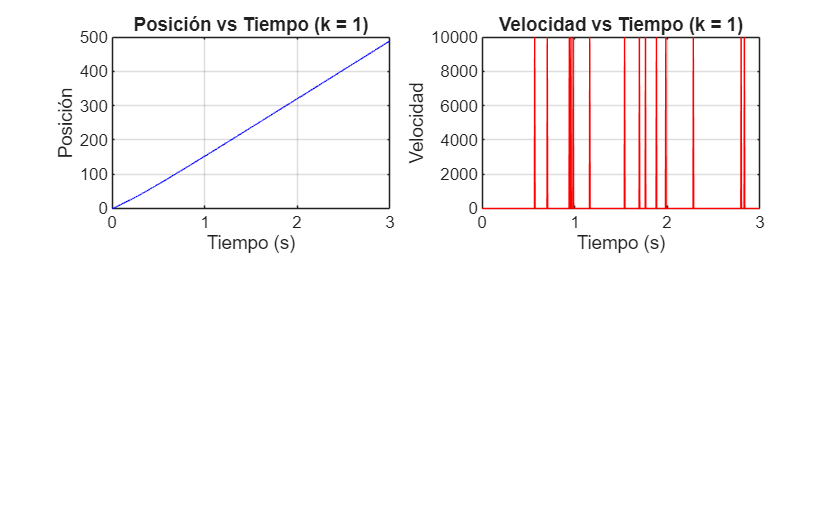

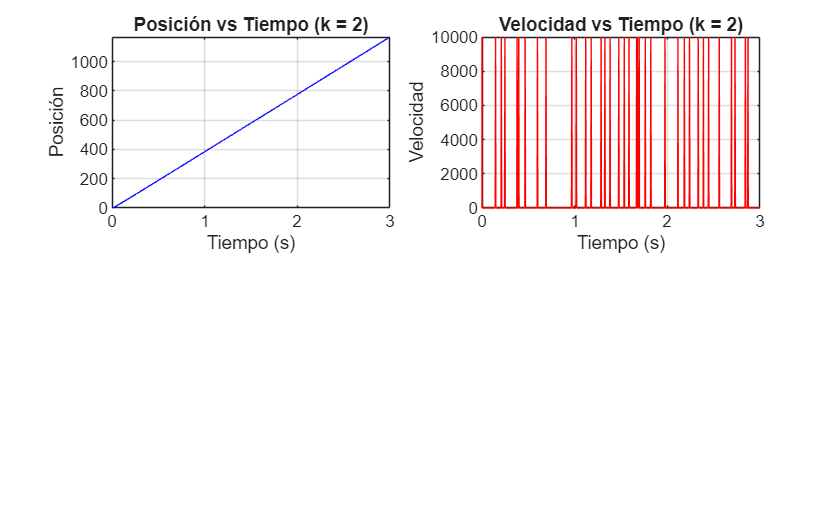

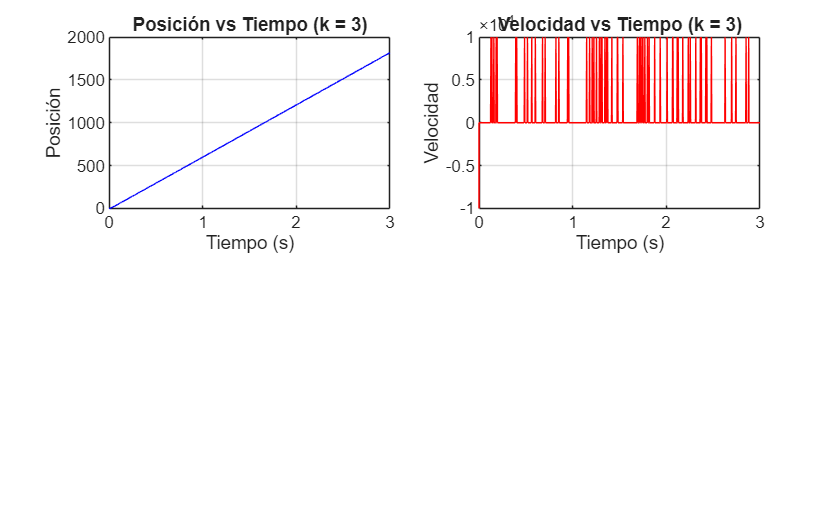

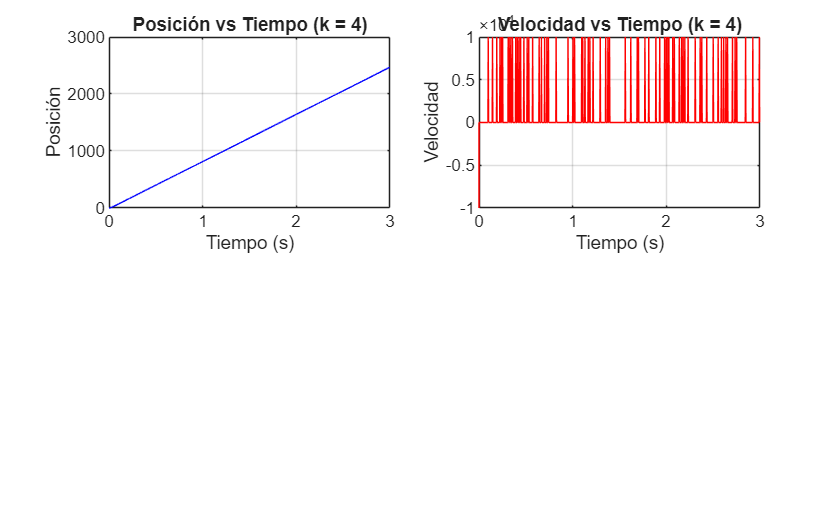

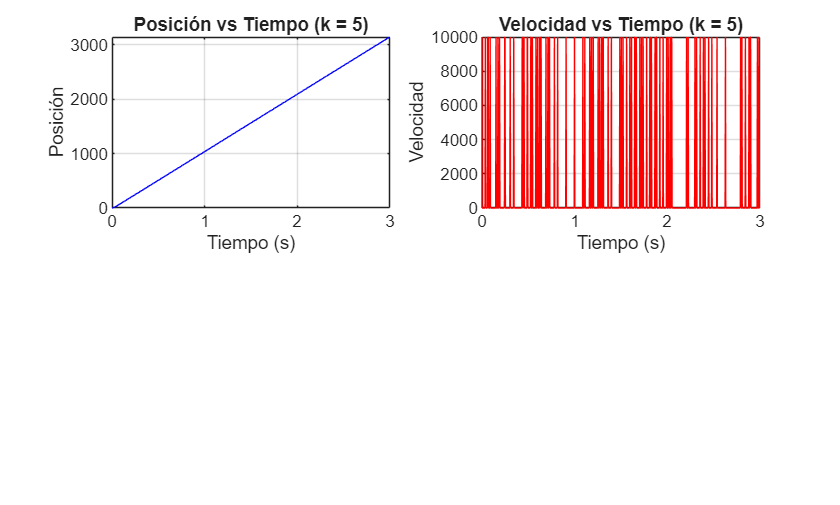

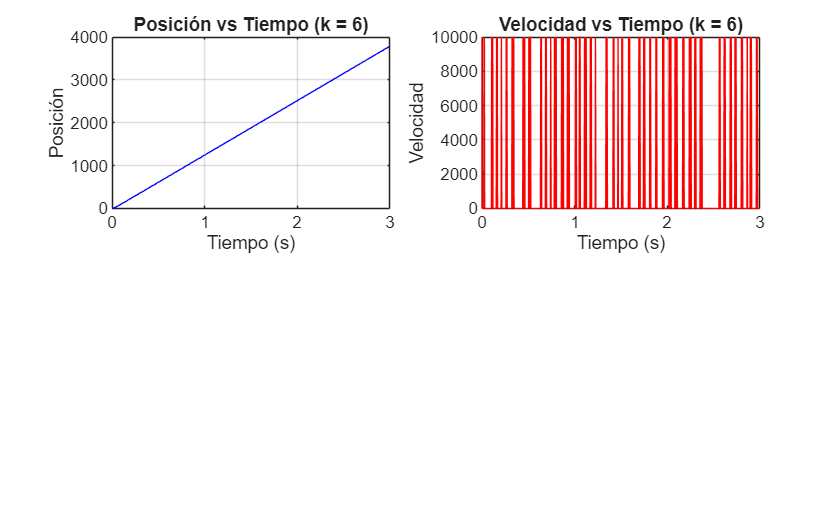

for k=1:6 % k es el archivo a analizar. Cambiar para elegir los datos
pos = d(k).data{1};
vel = d(k).data{2};

t1 = pos.Values.Time(:);
x  = pos.Values.Data(:);

t2 = vel.Values.Time(:);
v  = vel.Values.Data(:);


% Gráficas datos
figure(k);
subplot(2,2,1)
plot(t1, x, 'b')
xlabel('Tiempo (s)')
ylabel('Posición')
title(sprintf('Posición vs Tiempo (k = %.0f)', k));
grid on

subplot(2,2,2)
plot(t2, v, 'r')
xlabel('Tiempo (s)')
ylabel('Velocidad')
title(sprintf('Velocidad vs Tiempo (k = %.0f)', k))
grid on

end

Análisis posición

% Quito el 10% inicial de los datos (por el comportamiento exponencial)
N = length(x);          
Nrec = round(0.10*N);   

x_rec = x(Nrec+1:end); 
t_rec = t1(Nrec+1:end);  

% figure(10*k)
% plot(t_rec, x_rec, 'b')
% xlabel('Tiempo (s)')
% ylabel('Posición')
% title('Posición vs Tiempo (recortado)')
% grid on

En cada serie de datos, se calcula la pendiente ($m$) y la coordenada en el origen ($n$) del ajuste lineal de los valores de la posición angular. Y finalmente se obtienen $p$, $k_e$ a través de las siguientes expresiones.


$$p=-\frac{m}{\;n}\;\;\;\;;\;\;\;k_e =\frac{\textrm{mp}}{V}=-\frac{m^2 }{\textrm{nV}}$$


for i = 1:6
    [p(i),ke(i)] = sacar_p_ke(d,i);
end
p,ke

p =    10.2173   50.0951   46.8636   55.1242   58.3438   47.9846


ke = 1.0e+03 *

    0.8605    4.9133    4.7671    5.7091    6.1571    5.0848


p_medio = mean(p)

p_medio = 44.7714

ke_medio = mean(ke)

ke_medio = 4.5820e+03

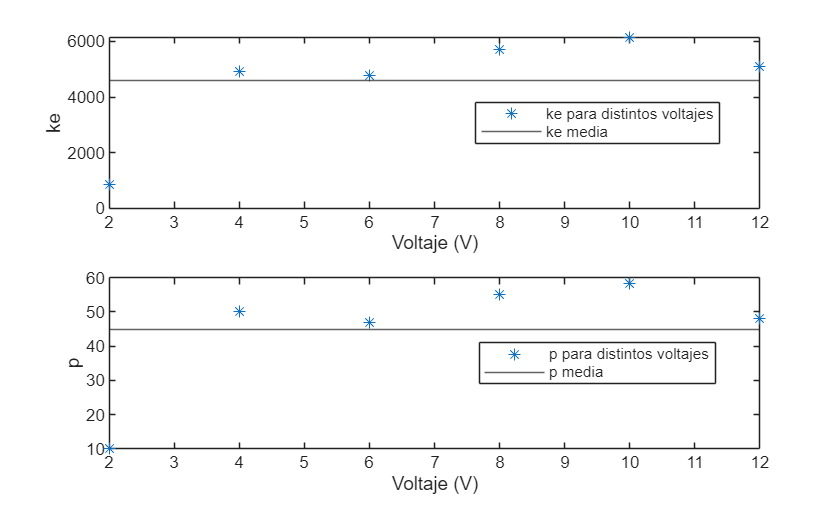

V = [2 4 6 8 10 12];

figure
subplot(2,1,1)
plot(V, ke, '*')
hold on
yline(ke_medio)
ylabel('ke')
xlabel('Voltaje (V)')
legend('ke para distintos voltajes', 'ke media', 'Location', 'best');

subplot(2,1,2)
plot(V, p, '*')
hold on
yline(p_medio)
ylabel('p')
xlabel('Voltaje (V)')
legend('p para distintos voltajes', 'p media', 'Location', 'best')

0.0

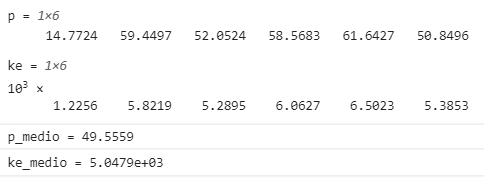

0.1

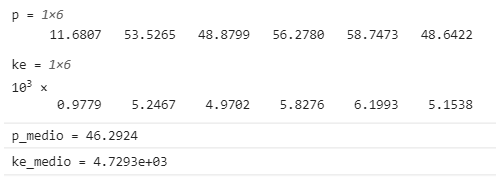

0.2

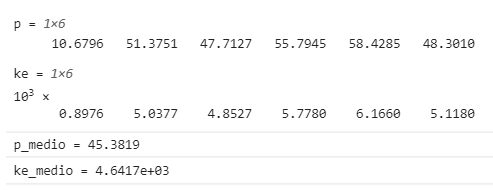

0.3

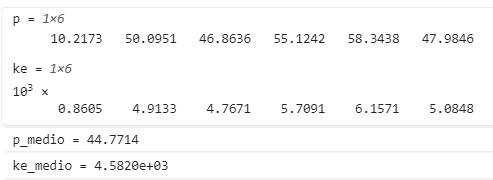

0.4

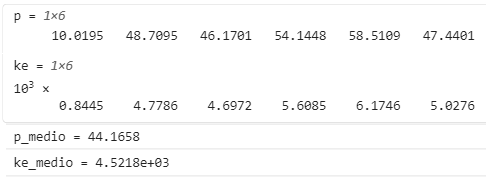

0.5

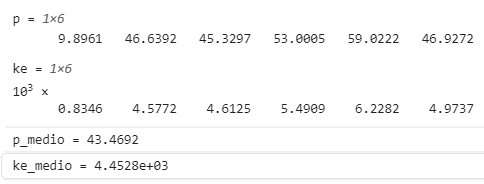

Funciones

function [p, ke] = sacar_p_ke(datos, k)
    pos = datos(k).data{1};
    vel = datos(k).data{2};

    t1 = pos.Values.Time(:);
    x  = pos.Values.Data(:);

    t2 = vel.Values.Time(:);
    v  = vel.Values.Data(:);

    %Análisis posición. Quitamos un % inicial de los datos (por el comportamiento exponencial)
    p_quitado = 0.3;
    N = length(x);          
    Nrec = round(p_quitado*N);   

    x_rec = x(Nrec+1:end); 
    t_rec = t1(Nrec+1:end); 

    %Cálculo de p, ke. 
    aj = polyfit(t_rec, x_rec, 1); %ajuste(1) es la pendiente (m), ajuste(2) la coord. origen (n)
    V=2*k; %(Es el voltaje. Lo podría cambiar aunque 2*k de momento sirve (k es el dato cargado)
    p = -aj(1)/aj(2);
    ke = -aj(1)^2/(aj(2)*V);
end